clear all
clc
addpath('./utils/')
addpath('./Realization')

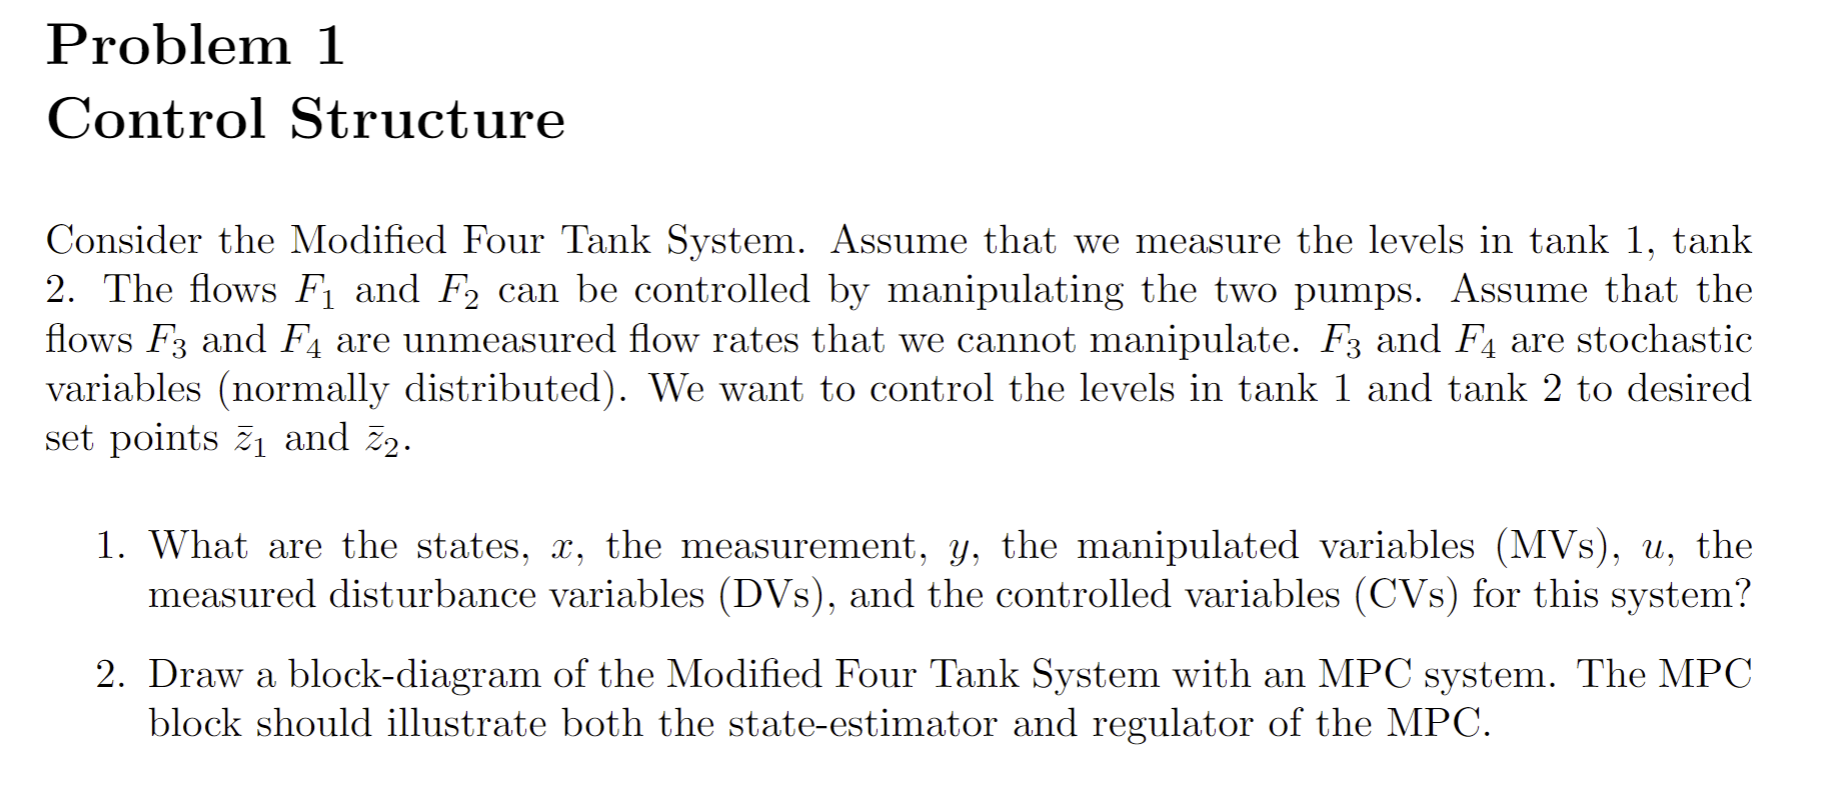

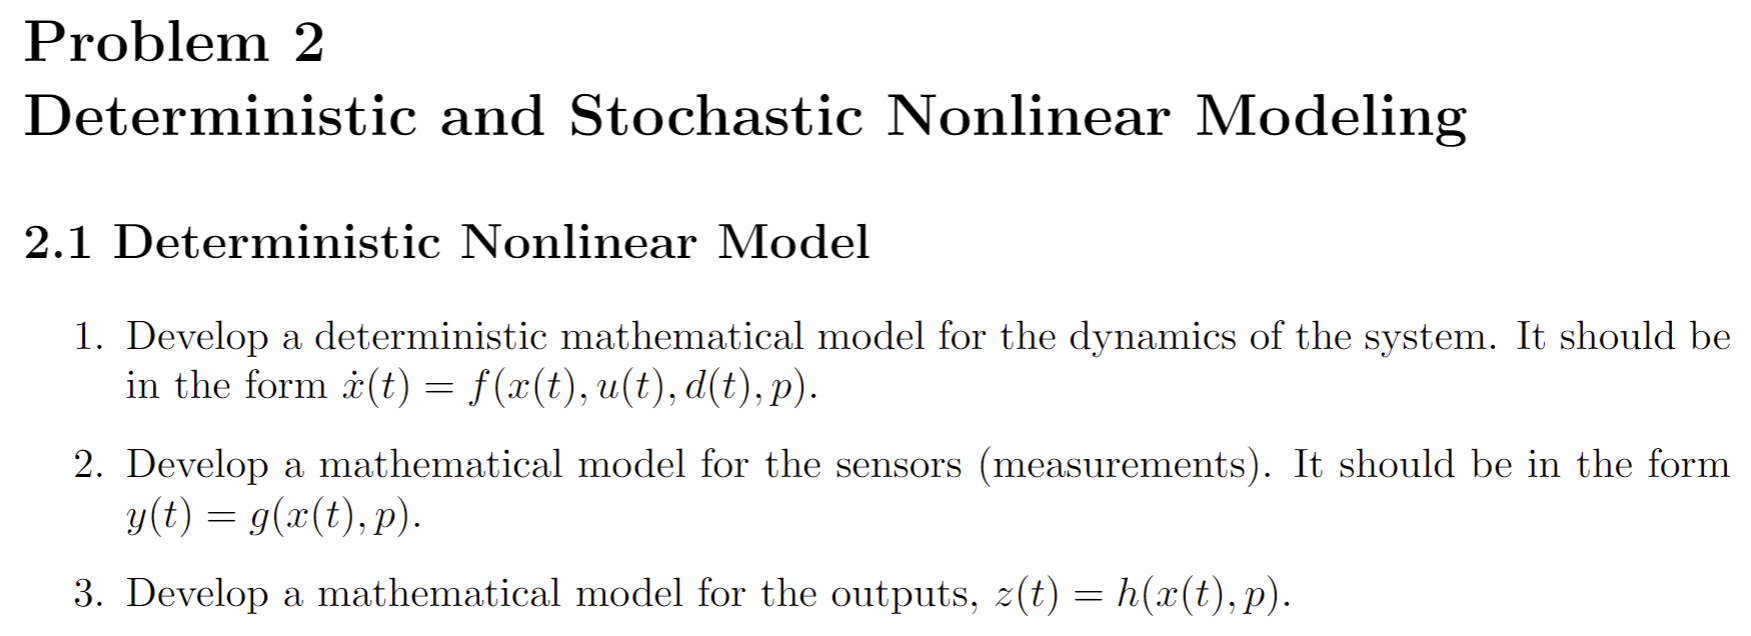

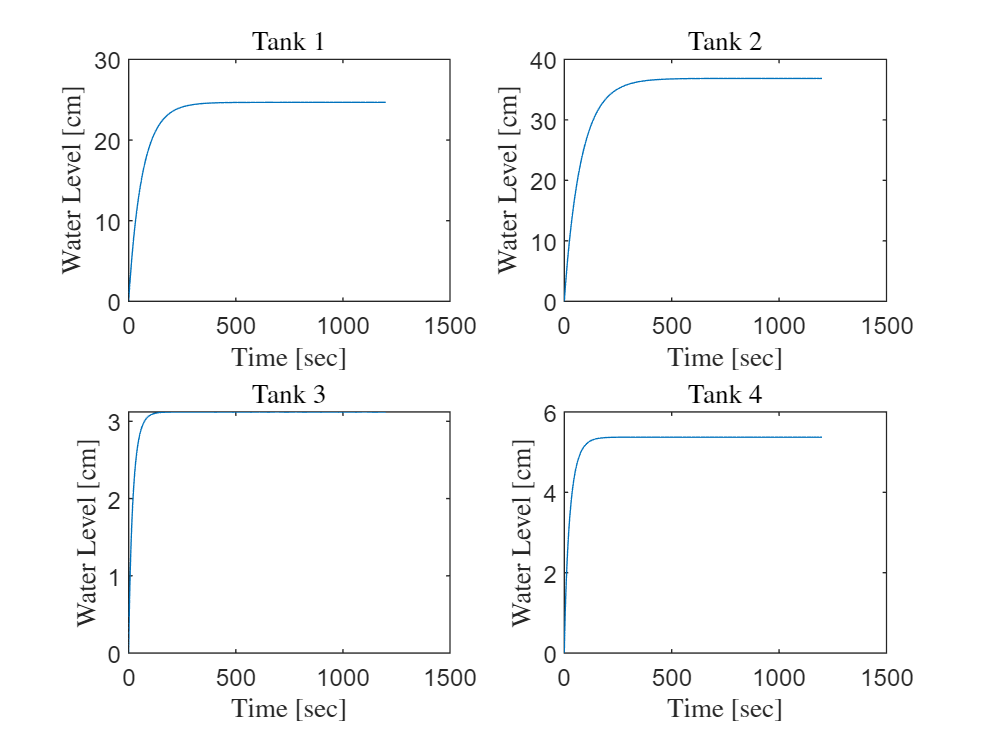

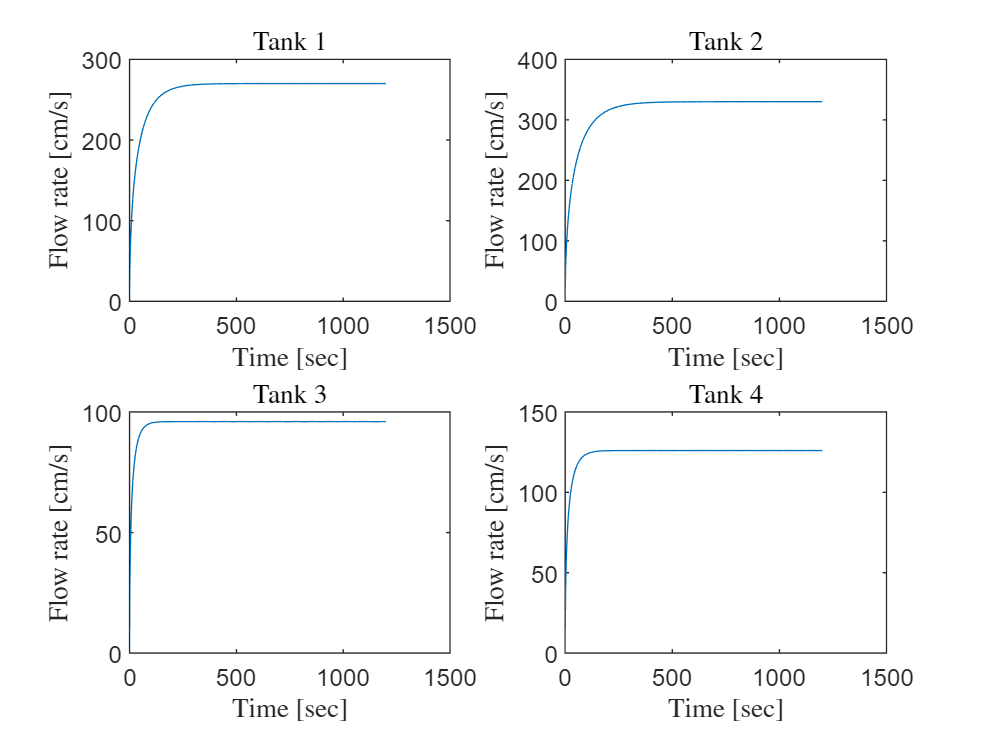

% get parameters
p = param();

%Flow input
U = 300;
%Disturbance
D = 0;

% flow rate steady state
F = [U U D D];

% simulate
[t y q] = sim_dem(F, p);

plotting(t, y, q, "Deterministic Nonlinear Model")

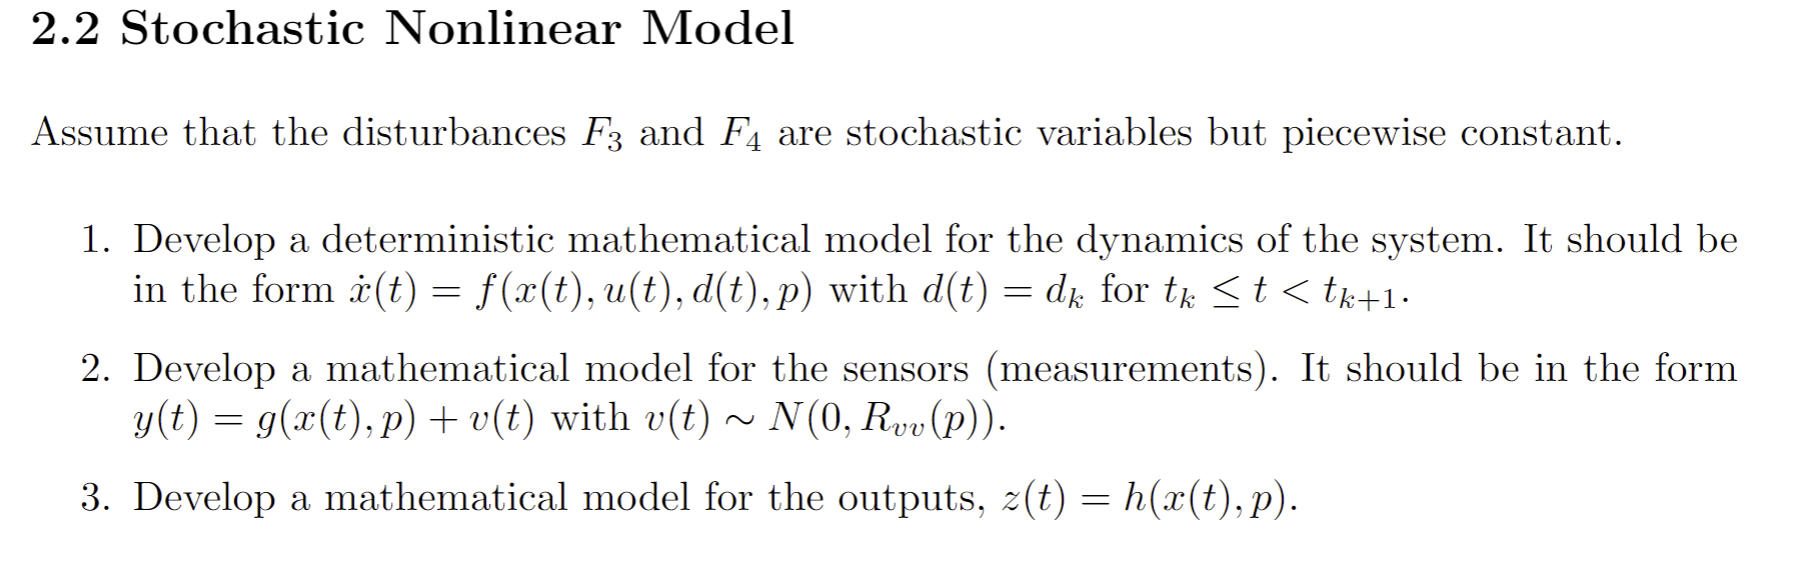

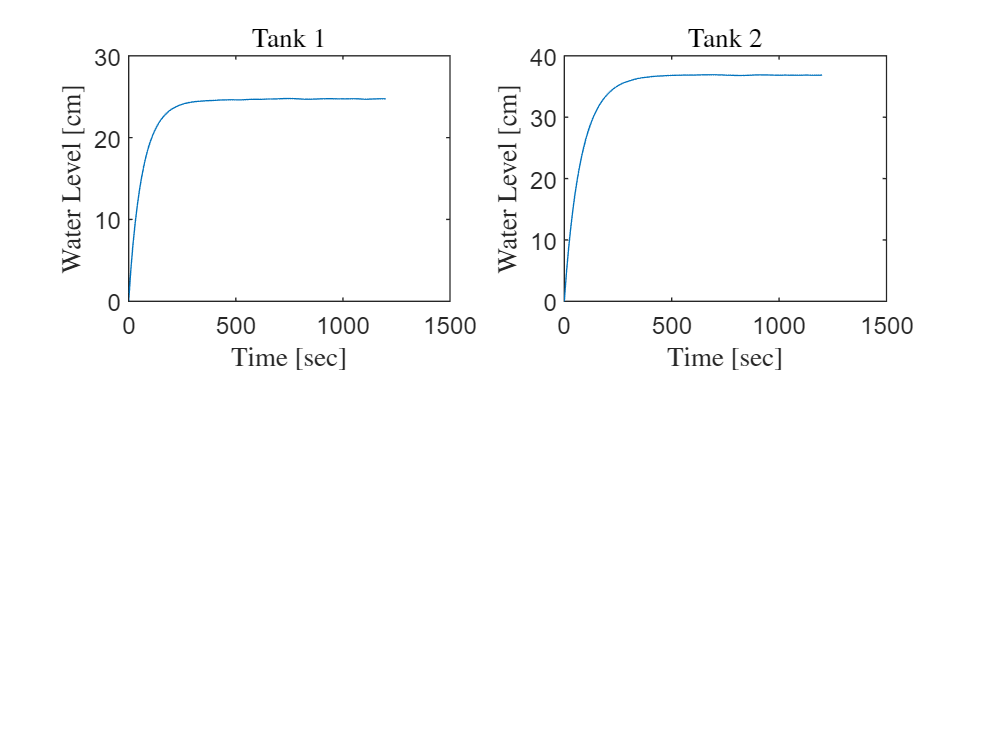

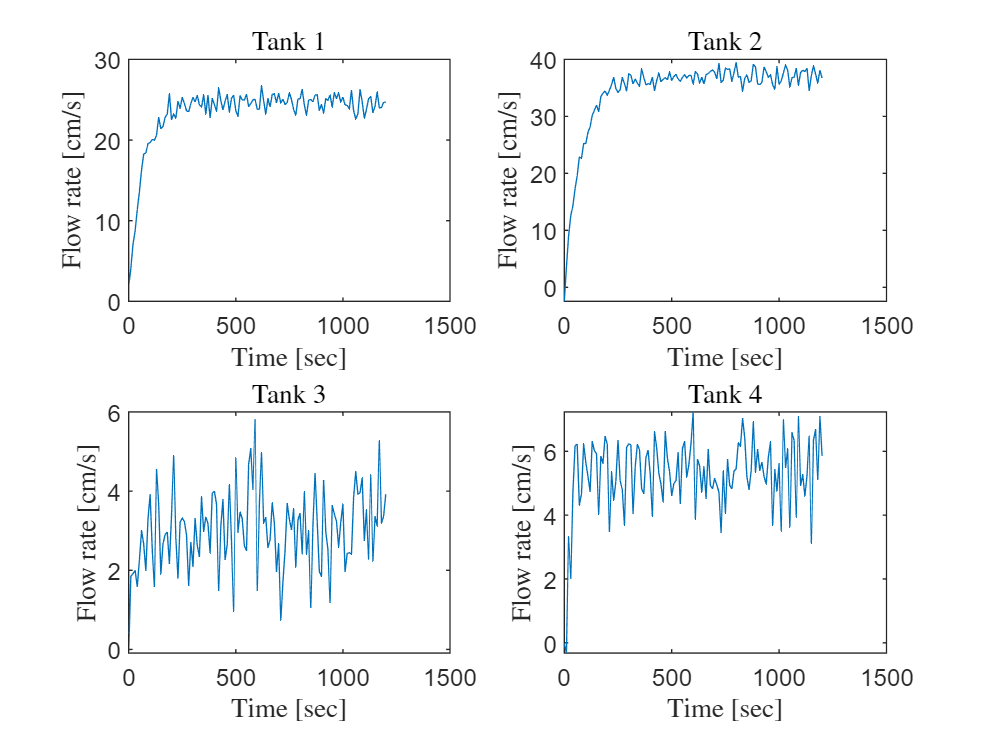

t0 = 0.0;
tfin = 20*60;
Ts = 10;
t = [t0:Ts:tfin];     % time vector
N = length(t);

F1 = 300;
F2 = 300;
u = [repmat(F1,1,N); repmat(F2,1,N)];   % control 

d = [randn(1,N); randn(1,N)];   % disturbances F3, F4
r = [13, 10, 4, 4];
parameters = param();

P = eye(1);
Pq = chol(P,'lower');

% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);


s = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
step_size = 0.01;
x(:,1) = [0;0;0;0];

for k = 1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function WITH noise 
    s(:,k) = FourTankSystemOutput(x(:,k),parameters);
    % Output function
    disturbance_without_noise = d(:,k); % +w(:,k);
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k):step_size:t(k+1)],x(:,k),[], ...
        u(:,k),disturbance_without_noise,parameters);
    x(:,k+1) = Xk(end,:)';
    % T = [T; Tk];
    X = [X; Xk];
end

k = N;
y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function
s(:,k) = FourTankSystemOutput(x(:,k),parameters);        % Output function

plotting(t, s', y', "Stochastic Nonlinear Model");

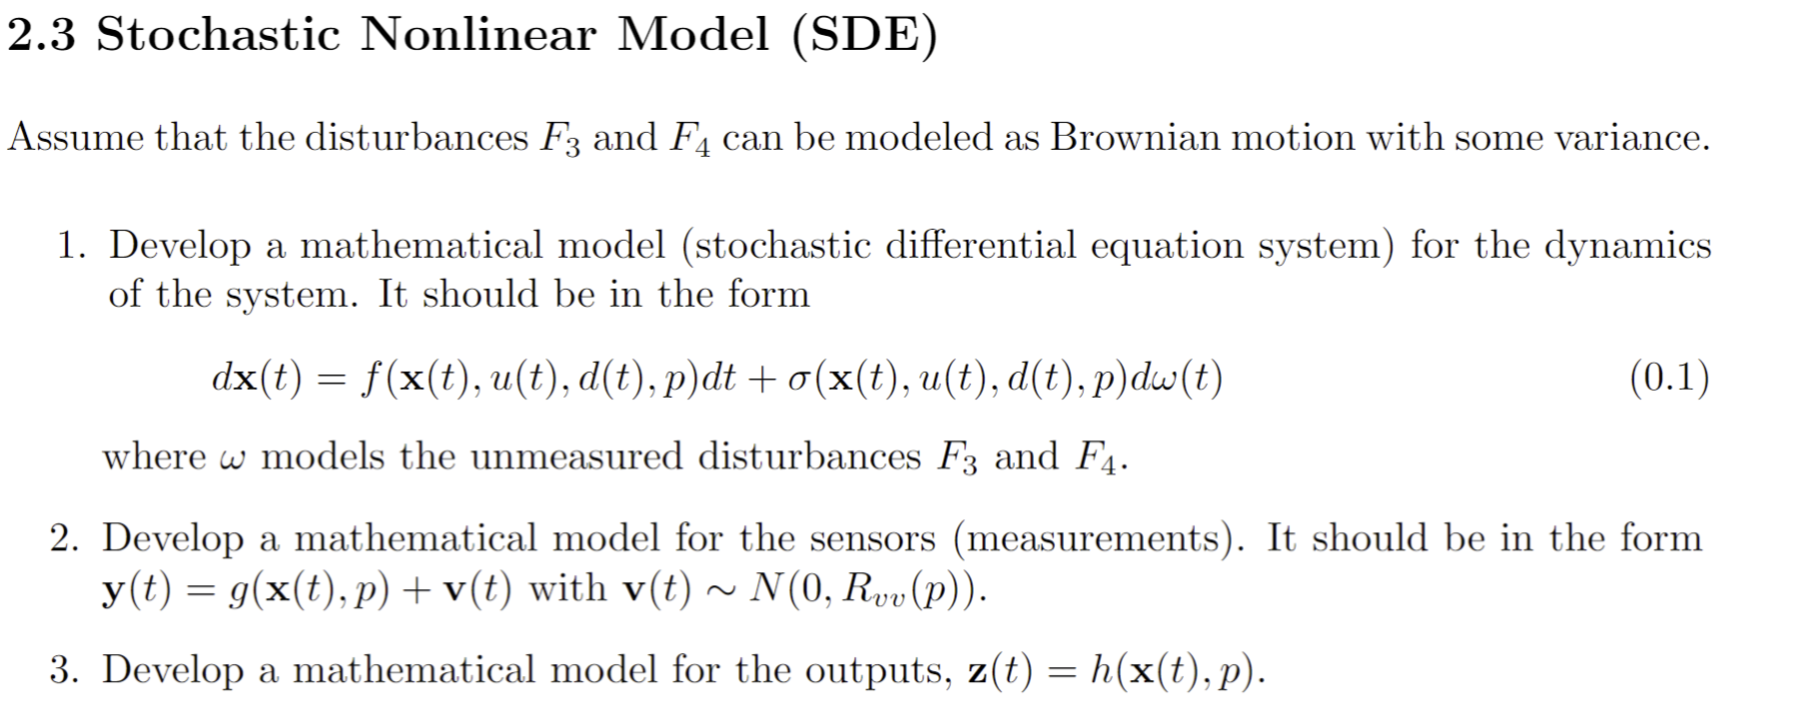

%

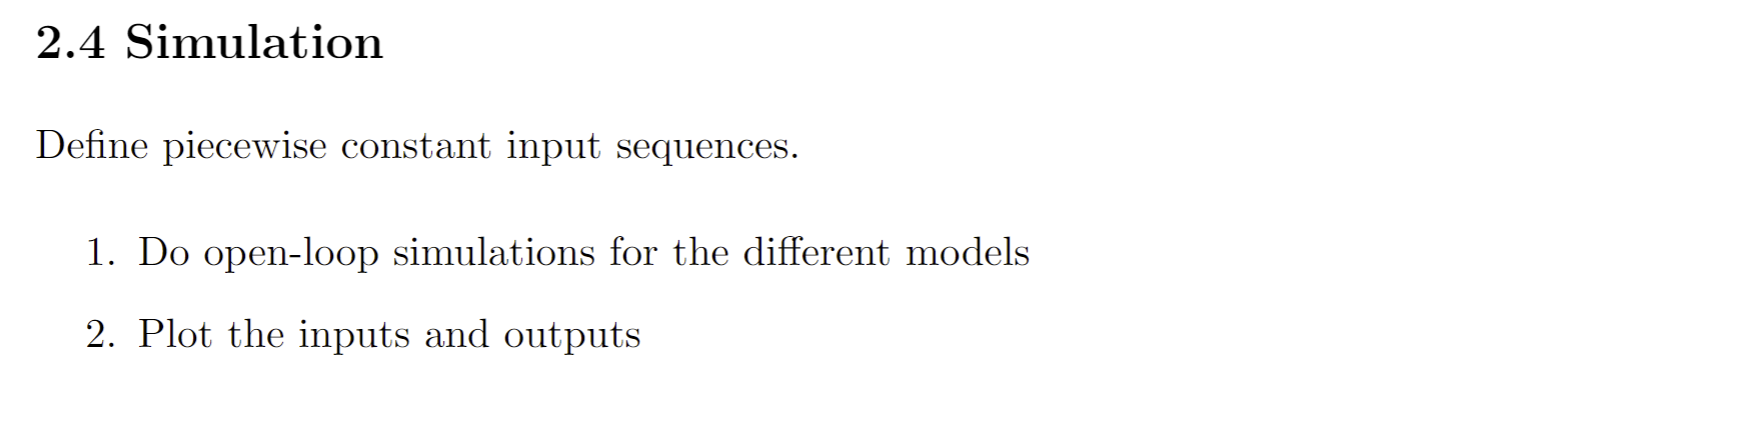

%

%

%

%

%

%

%

%

%

%

%

%
